# Tank level modelling and control

This livescript is a brief manual in support of the app ***tanklevel_story.mlapp***.   This is a simple interface to understand the entire design process of behaviour analysis, modelling  and PI control of simple tank level models, subject to changes in the core parameters such as tank volume, flow rate and external disturbances such as changes to the inlet flow, blockages in the outlet pipe, measurement noise and measurement delays. These notes give a concise engineering and analytical background alongside some simple MATLAB code snippets than can be used for equivalent analysis.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files uncomment and run either line of the code below:**

%  For documentation in a separate window type one of these 
%        Control101
%        doc Control101 Toolbox (pre 2024 only)
%        doc ("Control101 Toolbox")  
%        doc control101_toolbox. 
%  
%        help control101         (opens within the command window)

File written by J.A.Rossiter, University of Sheffield                         

## Table of contents

- Context of the tank system

- TAB 1: Open-loop step response analysis

- TAB 2: Modelling the tank

- TAB 3: Manual control ot tank depth subject to uncertainty

- TAB 4: Automatic control of depth with PI compensation

- TAB 5: Analysis of closed-loop behaviour with mutliple sources of uncertainty.

- Supporting MATLAB code for analysis

## 1. Context of the tank level system and app organisation

### 1.1 The app organisation

The app is organised into multiple tabs which gradually take the user through an entire control design process, beginning at modelling and finishing at control evaluation. Logically a user would begin a the first tab and work through these systematically. Figures in the following sections will show more detail.

- The top left contains sliders with which the user can set the main system values for the simulations. These sliders are used for all the tabs. 

- The top right has figures which are used for all the tabs.

- The tab window is in the bottom left and has the following options. When selecting a tab, the tab specific options will appear in that part of the window.

- Open-loop behaviour

- Open-loop modelling

- Manual control

- PI control

- Control with uncertainty

In general terms, the top right figure shows the most important response information and, includes memory of previous simulations where appropriate (tabs 1,2,4).

The top middle figure shows the illustration of the tank, its level and flow in.

The bottom right figure displays the input (flow in) signal and the values assumed for the environment parameters (e.g. blockages and disturbance in-flow).

The responses can be animated or not using the button in the top left. Animation allows the user to relate the behaviour to the real system, but it does mean waiting about 10 seconds between each simulation. Animation is essential in tabs 3 and 5 and cannot be turned off.

#### Remarks:

- The user can skip to any tab randomly should that be desirable; there should be no interdependencies apart from the very last tab which pulls the PI parameters from tab 4.

- Users may find it helpful to refresh the figures (button at top left) when moving to a new tab. This is not done automatically so that users do not unexpectedly lose some plots they may wish to save or go back to.

- In some tabs, you can disable the animation to see quicker responses using the 'animation on/off' button at the top left.

### 1.2 Engineering context

The figure below shows the maximum extent of the tank dimensions, so a width of upto 10 and a depth of 9. 

- The width/area can be modified by the user. 

- The water exits the tank from the outlet in the bottom right which has variable dimensions (linked to a conductance term *R*), again adjustable by the user. 

- The red rectangle represents a plug or bung which, from time to time moves down and acts as a blockage on the outlet pipe thus reducing its area and thus the corresponding outflow. The user can also vary the percentage overlap of this bung with the outlet.

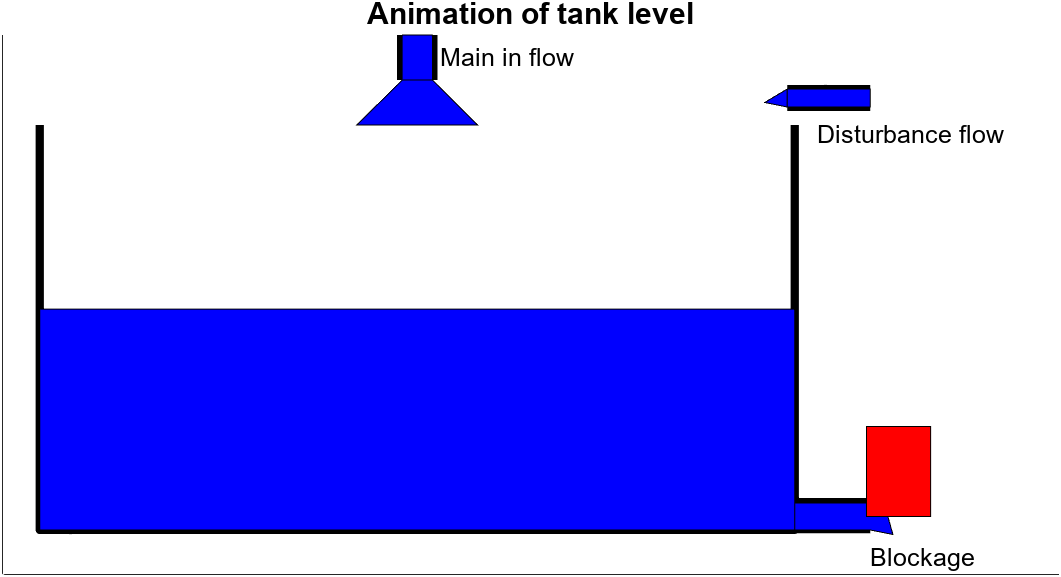

There are two input flows:

- the flow in the top centre is a controllable flow which the user adjusts to achieve the desired depth. This flow could be selected via open-loop or closed-loop mechanisms.

- the flow on the top right is a disturbance flow which again can be varied by the user. 

### Model of the tank system

Assume cross-sectional area *A* and that the flow out is dependent on the depth *h* through a conductance parameter *R*. Then, using a volume balance the equation for the depth is governed by;


$$A\frac{\textrm{dh}}{\textrm{dt}}+\textrm{Rh}=f_{\textrm{in}} ;\;\;\;\;f_{\textrm{in}} =f+d$$


where the flow in comprises the two components: *f* for controllable flow and *d* for disturbance flow. Blockage of the outlet pipe reduces the value of parameter *R*.

## 2. TAB 1: Open-loop behaviour analysis

The first tab supports open-loop analysis of behaviour and allows users to vary tank parameters such as cross-sectional area, outlet flow pipe size, flow in, disturbances and blockages and also the timing of the uncertainty so that the transient impact can be seen more clearly.

A simple model for the tank behaviour is derived using the time constant form below (assuming constant in flows). 


$$\frac{A}{R}\frac{\textrm{dh}}{\textrm{dt}}+h=\frac{1}{R}\left(f+d\right),\;\;\;\;T=\frac{A}{R},\;\;\textrm{Gain}=\frac{1}{R}$$



$$h\left(t\right)=$$

$$\frac{1}{R}\left(f+d\right)-$$

$$\left(h\left(0\right)-\frac{1}{R}\left(f+d\right)\right)$$

$$e^{-\frac{t}{T}}$$


The blockage is assumed to have a direct percentage change on the value *R*. Thus

$R\to R\left(1-B\right)$where ***B*** is the percentage/fractional blockage.

### 2.1 Impact of changes in in-flow

The in-flow* f* effects the steady-state values, so:


$$\lim_{t\to \infty } h\left(t\right)=\frac{1}{R}\left(f+d\right)$$


Thus, ignoring the disturbance term for now, the core relationship is: $h_{\textrm{ss}} =\frac{f}{R}$

### 2.2 Impact of changes in area

The area affects the time constant through the relationship: $T=\frac{A}{R},$

As area increases, the time constant becomes slower.

### 2.3 Impact of changes in disturbance flow

The disturbance flow is similar to the in-flow in how it impacts on behaviour. So a change in disturbance flow leads to a change in the steady-state depth as follows: $\delta h_{\textrm{ss}} =\frac{d}{R}$

### 2.4 Impact of changes in the blockage

As the blockage impacts on the conductance term R, it impacts on both the steady-state and the time constant.


$$T=\frac{A}{R\left(1-B\right)},\;\;\textrm{Gain}=\frac{1}{R\left(1-B\right)}$$


Hence an increase in the blockage causes an increase in the steady-state and an increase in the time constant.

Some illustrations of the tab and the record keeping for different options is given below. 

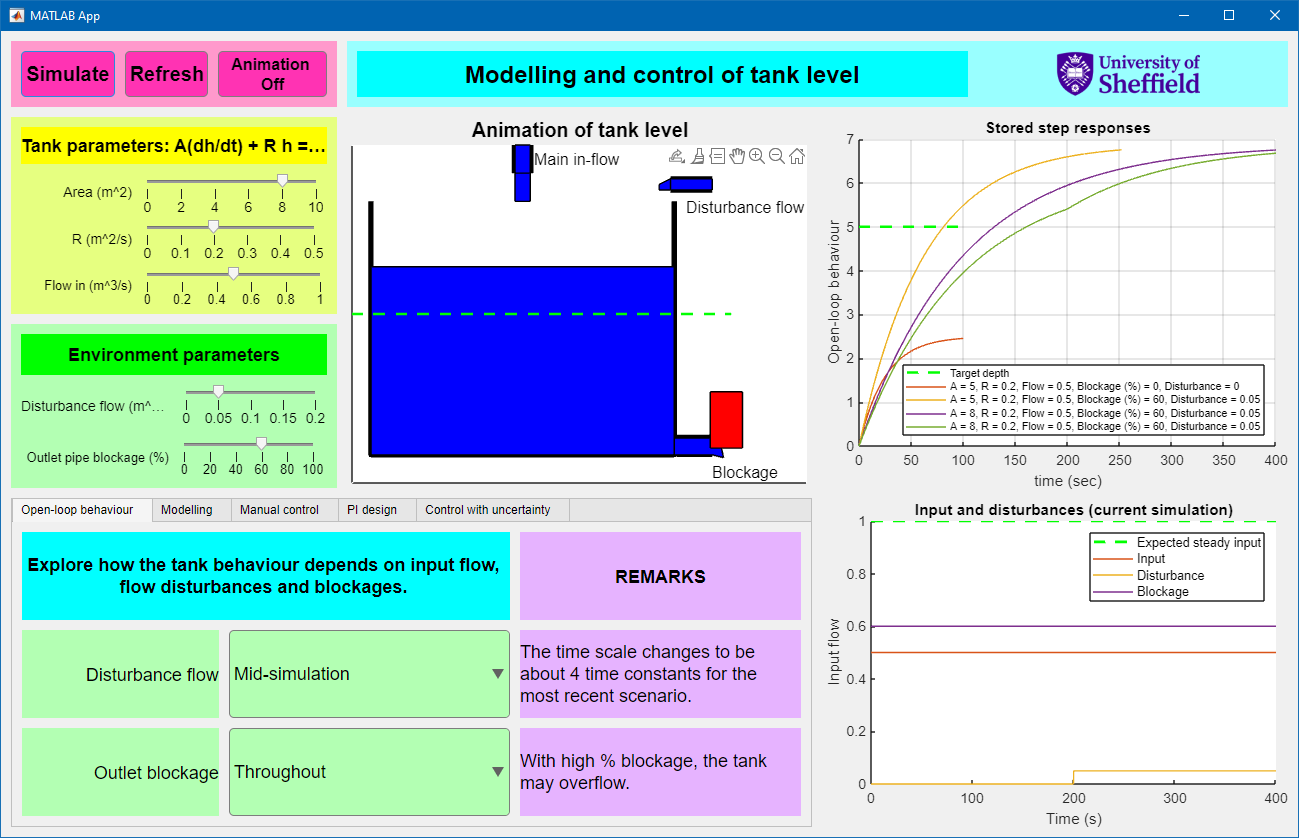

## 3. TAB 2: Modelling the tank

The second tab invites students to form a data based model of the tank in time constant form and provides tools and analysis to support this process.

A standard first order analysis is covered in numerous other files such as***: firstordermodels_response_characterisation.mlapp*** and [`firstordermodels_responses_analysis_and_feedback.m`](matlab: firstordermodels_responses_analysis_and_feedback)

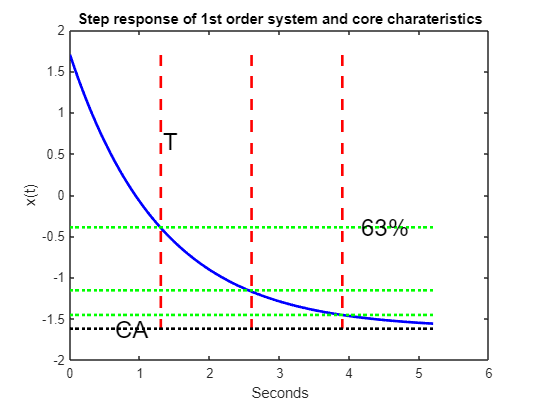

The core point is to identify the time constant T and steady-state gain C. From a unit step response, the steady-state value will be the gain multiplied by the input magnitude A and we get 63% movement after T seconds, hence both these values can be determined quickly. Hence we find a model in time constant form, e.g.


$$T\frac{\textrm{dh}}{\textrm{dt}}+h=C\left(f+d\right)$$


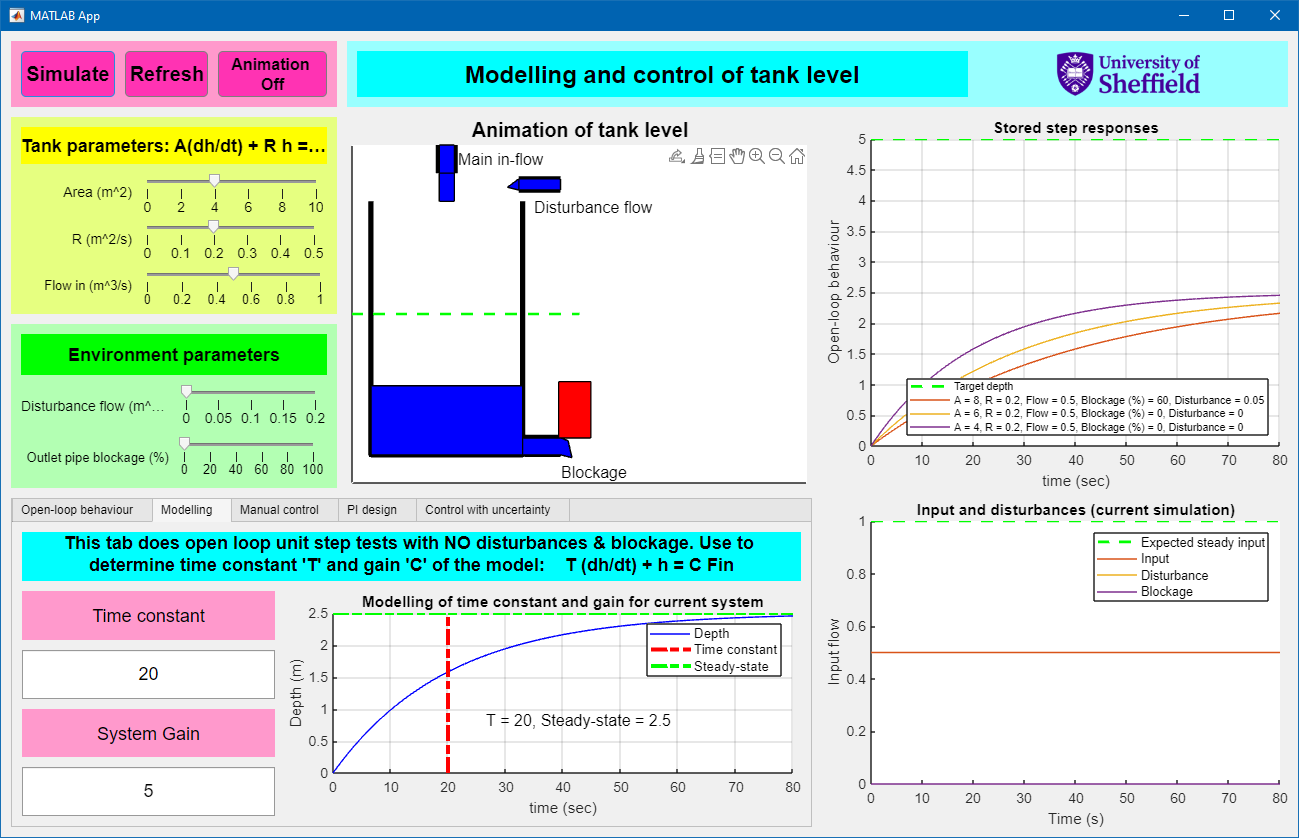

## 4. TAB 3: Manual control to tank depth subject to uncertainty

The third tab allows users to explore the concept of feedback control using a human in the loop; in essence the user is the controller. We call this manual control.

As noted in section 2, the behaviour changes when there are blockages and input flow disturbances. In practice we may wish to keep the depth at a specified level. We achieve this by relative simple rules such as:

- Monitoring the depth.

- If the depth is too high, reduce the input flow.

- If the depth is too low, increase te input flow.

- In practice, humans are a little more insightful in the rules they use to achieve this.

Users are invited to try this process on the tank by moving a slider to change the input flow while a range of disturbances are introduced randomly. It will become apparent quite quickly that manual control is not simple and moreover is rather tedious.

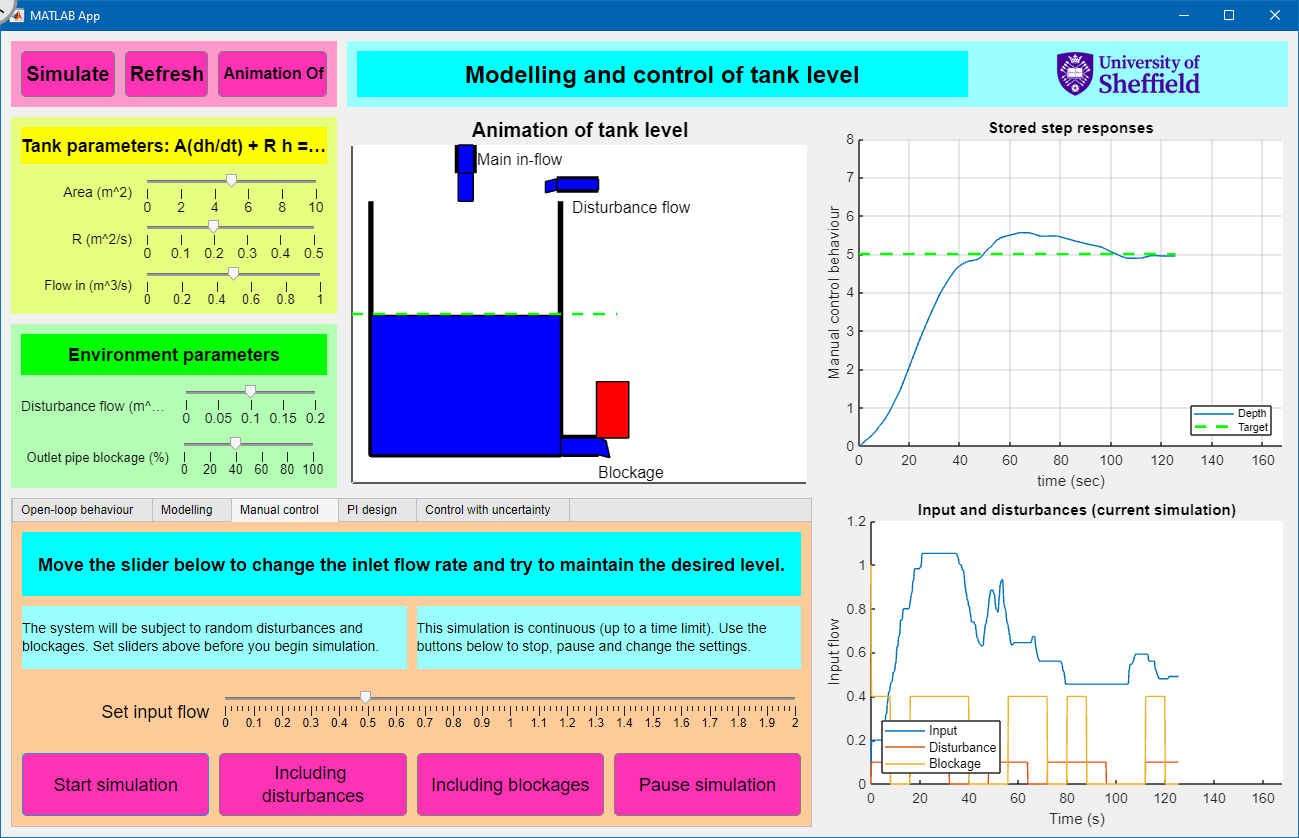

## 5. TAB 4: Automatic control of depth with PI compensation

The fourth tab moves on the automatic control. We realise that manual control is not practical as humans are both unreliable and expensive. We would like the inlet flow rate to be computer controlled as computers are, by comparison, both cheap and reliable. However, a computer needs a rule base with which to determine the appropriate inlet flow. An industrially popular rule base is called proportional and integral, that is:

$f\left(t\right)=K_p e\left(t\right)+K_i \int_0^t e\left(t\right)\textrm{dt}$, where ***e(t)*** is the error between the desired depth and the actual depth. 

There are standard rules for the selection of the parameters $K_p ,K_i \;$but a simple rule base is as follows:


$$K_p =\frac{1}{R};\;K_i =\frac{1}{\textrm{RT}}$$


Users can experiment with this choice, and others using the app. Moreover, they can explore the impact of disturbances on the efficacy of this, and other, design choices. For example, what happens to the efficacy of this law if there is an unexpected and large blockage?

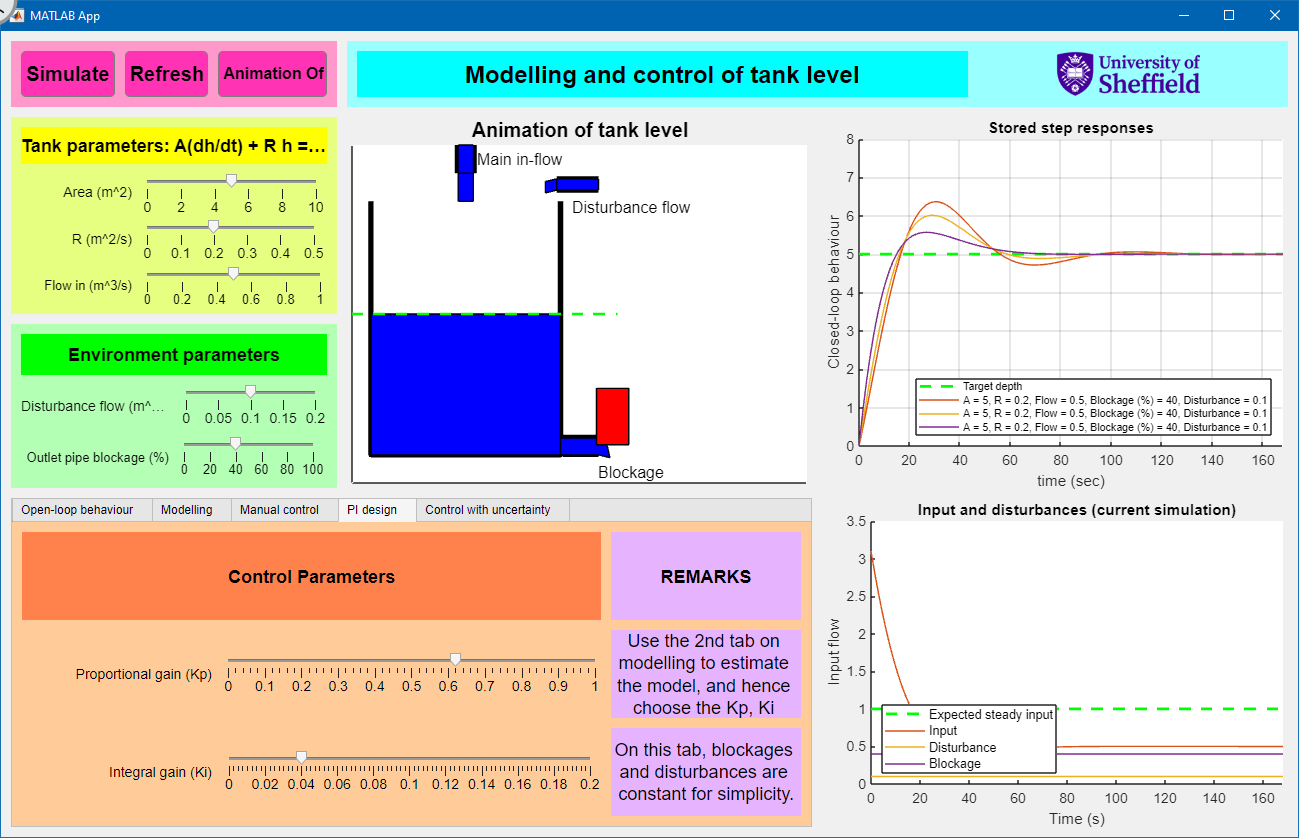

## 6. TAB 5: Analysis of closed-loop behaviour with multiple sources of uncertainty.

In the real world there are more diverse sources for uncertainty, and thus the last tab gives the user  the opportunity to assess their PI design in a more authentic scenario where the uncertainty appears randomly and chaotically. Does the PI still manage to keep the depth at the desired target (square wave dashed green line)?

The uncertainty can be switched on and off using the buttons at the bottom.

- Inlet flow disturbances

- Temporary partial blockages of hte outlet pipe.

- Measurement noise

- Measurement delay

When switched on, a given source of uncertainty will change randomly every 30 seconds; a record of this is available in the figure in the bottom right. 

The aim of the feedback is to bring the depth (top right figure) back to the desired level.The red and blue lines in the  top right figure show the difference between the true depth and the measured depth.

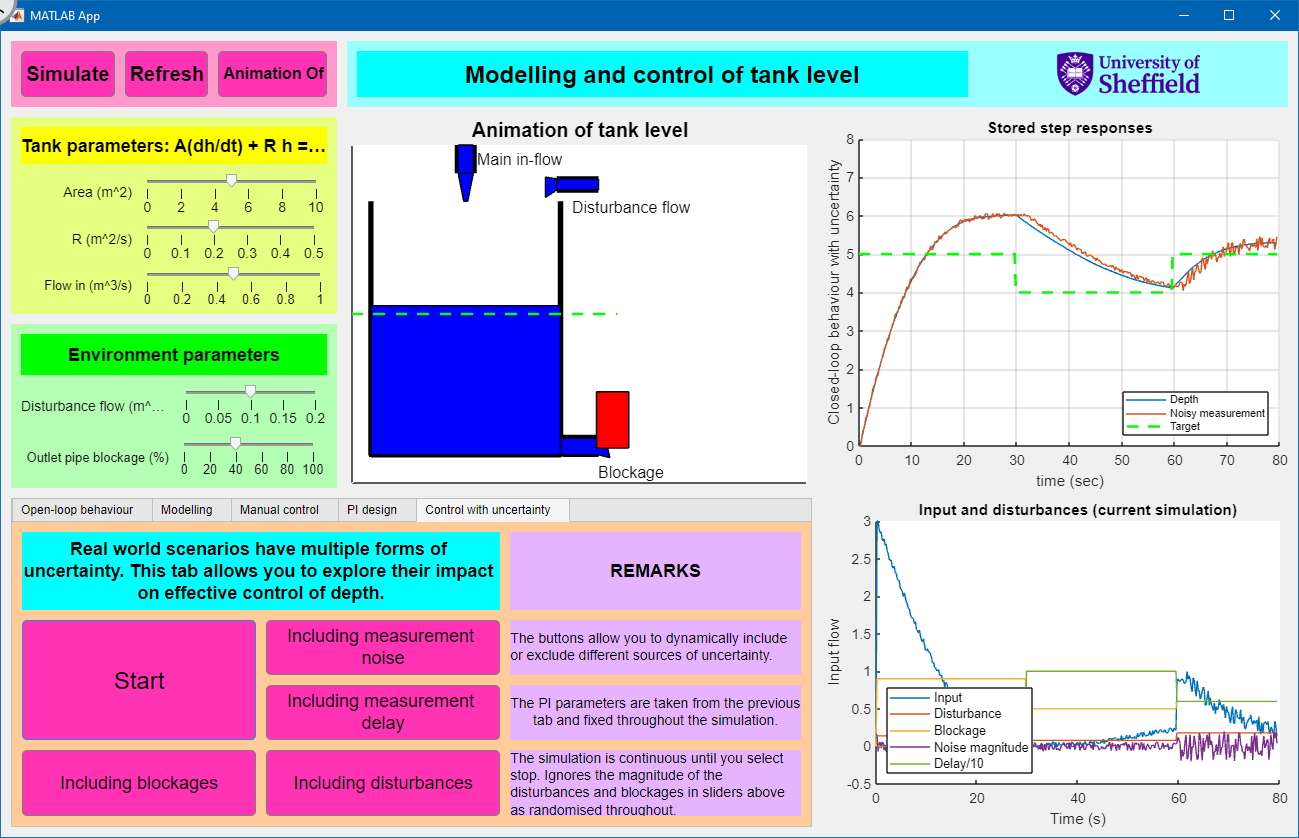

## 7. Supporting MATLAB code for analysis

For simplicity one can use Laplace transforms and step.m to form the generic open-loop model and the corresponding step response.


$$A\frac{\textrm{dh}}{\textrm{dt}}+\textrm{Rh}=f_{\textrm{in}}$$


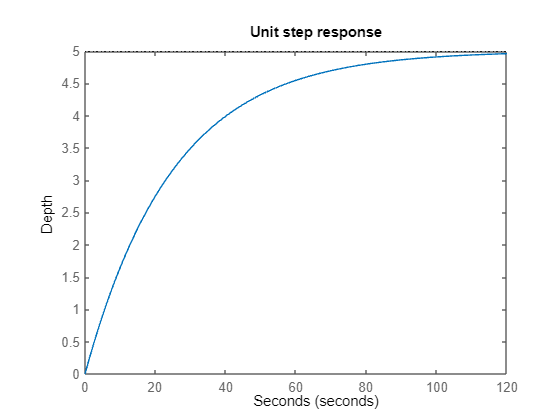

A = 5; R=0.2;
G = tf(1,[A,R]);
step(G,120)
title('Unit step response')
xlabel('Seconds')
ylabel('Depth')

### **7.1 Changes in the magnitude of the in-flow**

The function step.m assumes that f=1. Collecting and plotting the outputs separately allows for different magnitudes of f.

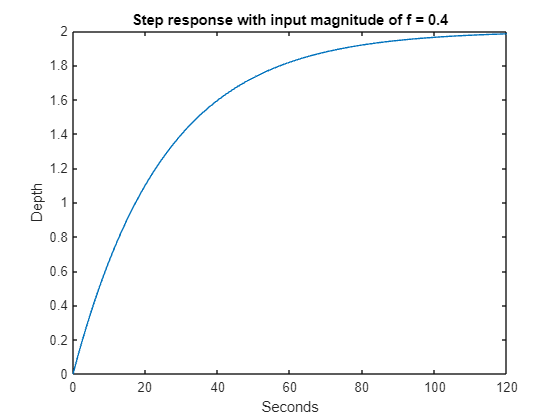

A = 5; R=0.2; f=0.4;
G = tf(1,[A,R]);
[y,t]=step(G,120);
plot(t,y*f)
title(['Step response with input magnitude of f = ',num2str(f)])
xlabel('Seconds')
ylabel('Depth')

### **7.2 Changes in the disturbance flow**

The function ***step.m*** can be used to determine the response for d=1. One can then scale to find the response for different values and use superposition to see the impact alongside the main in-flow. 

It will be clear that adding a disturbance flow, perhaps unsurprisingly, increases the steady-state.

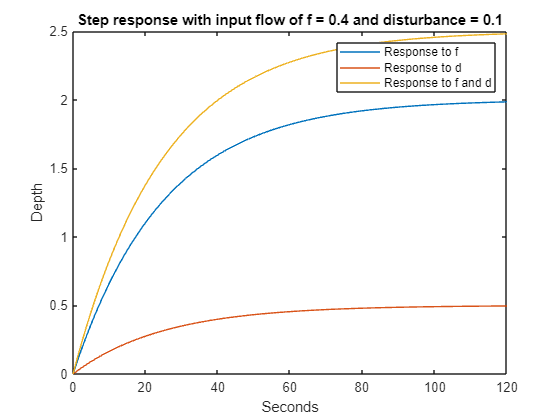

A = 5; R=0.2; f=0.4; d=0.1;
G = tf(1,[A,R]);
[y,t]=step(G,120);
plot(t,y*f,t,y*d,t,y*(d+f))
title(['Step response with input flow = ',num2str(f),' and disturbance = ',num2str(d)])
legend('Response to f','Response to d','Response to f and d')
xlabel('Seconds')
ylabel('Depth')

### **7.3 Impact of changes in area**

One can overlay the responses with different areas by producing a number of different models and the associated behaviours.

 It will be clear here that the time constant changes (increases as *A* increases) but the steady-state is the same.

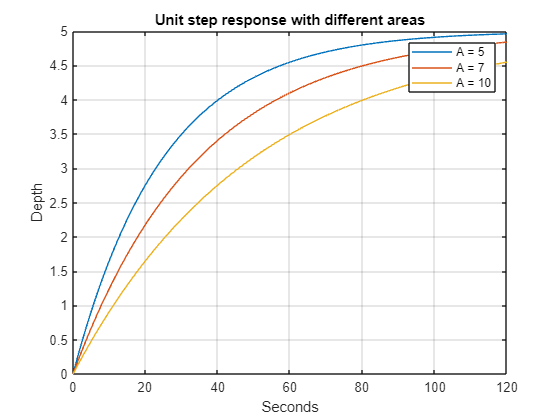

A1 = 5; A2 = 7; A3 =10;
R=0.2; f=0.4;
G1 = tf(1,[A1,R]);
G2 = tf(1,[A2,R]);
G3 = tf(1,[A3,R]);
[y1,t]=step(G1,120);
[y2]=step(G2,t);
[y3]=step(G3,t);
plot(t,y1,t,y2,t,y3);grid
title(['Unit step response with different areas'])
legend(['A = ' num2str(A1)],['A = ' num2str(A2)],['A = ' num2str(A3)])
xlabel('Seconds')
ylabel('Depth')

### **7.4 Impact of blockages**

This is easiest illustrated by having multople models to represent different blockages.

It is clear from the plots that as the blockage grows the time constant gets slower and the steady-state increases.

A = 5; 
B1=0; B2=0.20; B3 = 0.50;

B1 = 0

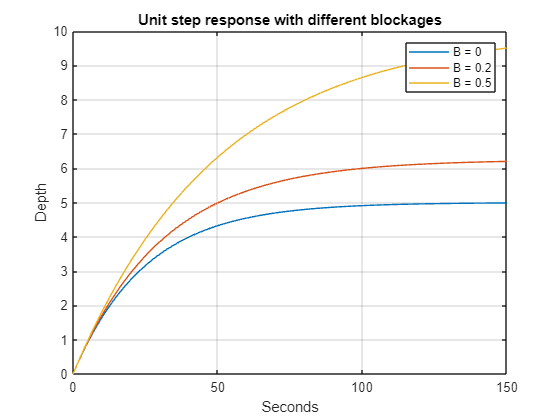

R=0.2; f=0.4;
G1 = tf(1,[A,R*(1-B1)]);
G2 = tf(1,[A,R*(1-B2)]);
G3 = tf(1,[A,R*(1-B3)]);
[y1,t]=step(G1,150);
[y2]=step(G2,t);
[y3]=step(G3,t);
plot(t,y1,t,y2,t,y3);grid
title(['Unit step response with different blockages'])
legend(['B = ' num2str(B1)],['B = ' num2str(B2)],['B = ' num2str(B3)])
xlabel('Seconds')
ylabel('Depth')

### 7.5 Further MATLAB code

For more information on coding, analysis and design of feedback loops, the user is directed to the appropriate files in the tool box such:

[`closedloop_transferfunctions_with_feedback.m`](matlab: closedloop_transferfunctions_with_feedback)

[`closed_loop_compare_multiple_compensators.m`](matlab: closed_loop_compare_multiple_compensators)

[`closedloop_offset_and_poles.m`](matlab: closedloop_offset_and_poles)